# Solution to *Following a Flight III* exercise

The `flightData` file includes information on which air traffic control tower the flight was in contact with at what times. In this exercise, you will add this information to the plot.

## Load data and create plot from previous exercise

Load the data from the file `flightData.mat`. The variables represent the time (`t`) in minutes after takeoff from LAX and the altitude (`altitude`) in feet above sea level.

load flightData

Define `tBad`, the time at which a bad data point occurred.

tBad = 257;

Using MATLAB commands, replace the value of the altitude at time `tBad` with the average of the altitude at times `tBad-1` and `tBad+1`.

altitude(tBad) = 1/2*(altitude(tBad-1)+altitude(tBad+1));

Plot the altitude of the aircraft versus the time in black with points as markers and a solid line connecting the points. Make sure to include a title and axes labels.

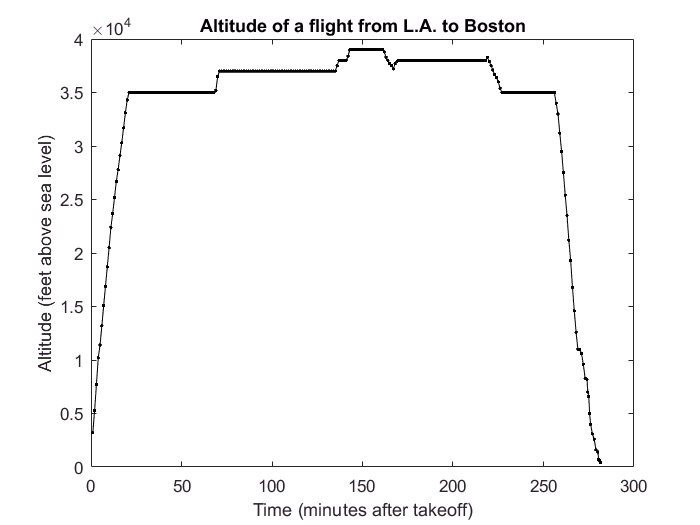

plot(t,altitude,'k.-')
title('Altitude of a flight from L.A. to Boston')
xlabel('Time (minutes after takeoff)')
ylabel('Altitude (feet above sea level)')

## 1. Plot vertical lines representing the transtions between centers

Starting with the plot from the previous exercise, plot vertical lines at the times between centers to separate the graph into regions. This information in stored in the centers variable. For example, the transition from the Los Angeles to Denver centers occurred at *t* = 46; draw a vertical line at *t* = 46 to indicate this transition.

Any line is defined by two points. For this exercise, the lower point of the desired vertical line has coordinates $(x_1,y_1)$ where $x_1$ is the time of the transition and $y_1$ is the minimum altitude of the flight (or 0 is just as acceptable). The upper point has coordinates $(x_2,y_2)$ where $x_2$ is the time of the transition (so $x_2 = x_1$) and $y_2$ is the maximum altitude of the flight. 

When you plot, the PLOT command requires the list of x values first and the y values second. See centers and cities variables for center coordinates and regions.

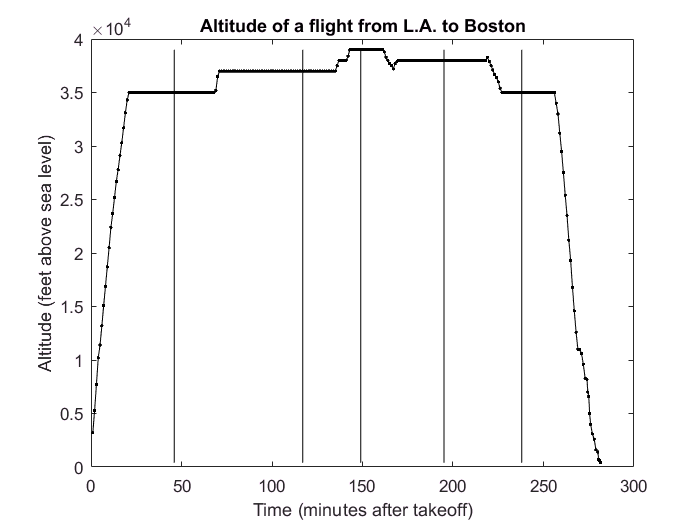

hold on
minAlt = min(altitude);
maxAlt = max(altitude);

plot([centers(1) centers(1)], [minAlt maxAlt],'k')
plot([centers(2) centers(2)], [minAlt maxAlt],'k')
plot([centers(3) centers(3)], [minAlt maxAlt],'k')
plot([centers(4) centers(4)], [minAlt maxAlt],'k')
plot([centers(5) centers(5)], [minAlt maxAlt],'k')

hold off

## 2. Add the text

Add text on your plot to indicate which center each region of your graph corresponds to. 

(**Hint** For more help, enter `doc text`. If you need to move or delete text after you display it, use the plot tools. Use the three-letter codes that are given in the `cities` variable as the text.)

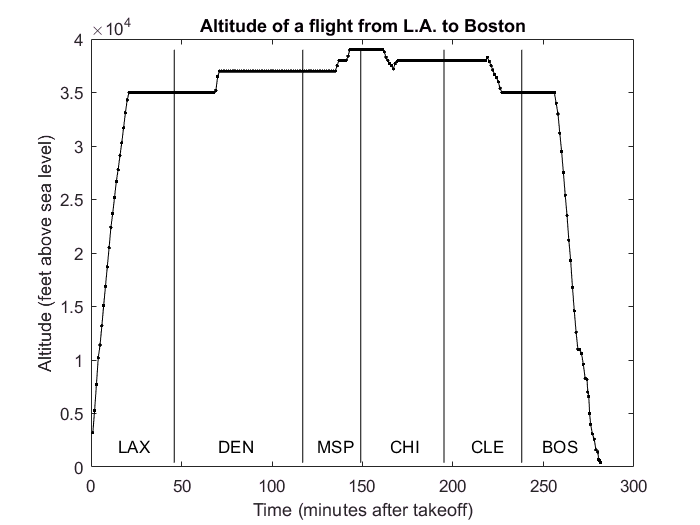

text(15,2000,cities(1,:))
text(70,2000,cities(2,:))
text(125,2000,cities(3,:))
text(165,2000,cities(4,:))
text(210,2000,cities(5,:))
text(249,2000,cities(6,:))